# AAE 532 EXAM3 Problem 1

clear all; close all; clc;

 % Default parameters
 earth.gp = 4.0000*10^5;  % earth gravitational parameter
 earth.r = 6400;  % earth radius
 sun.gp = 1.3e11;  % sun gravitational parameter
 sun.r = 7e5;  % sun radius
 jupiter.gp = 1.3e8;  % jupiter gravitational parameter
 jupiter.r = 7e4;  % jupiter radius
 AU = 1.5e8;  % sun to earth semi major axis

## Part (a)

% Comet
a_comet = 8*AU;  % semi major axis of comet with respect to the sun 
e_comet = 0.8;  % eccentricity of the comet 
p_comet = a_comet*(1 - e_comet^2)  % semi latus rectum of the comet

p_comet = 4.3200e+08

h_comet = sqrt(sun.gp * p_comet)  % specific angular momentum of the comet

h_comet = 7.4940e+09


% Jupiter at rendezvous
r_jup = 5.2*AU;  % the radial distance of jupiter with respect to the sun 
FPA_jup = 5;  % the flight path angle of jupiter [degree]
v_jup = 13.0;  % velocity of jupiter 
TA_jup = 90;  % true anomaly of jupiter [degree]
a_jup = -sun.gp / 2 / (v_jup^2 / 2 - sun.gp / r_jup)  % SMA of jupiter with respect to the sun

a_jup = 7.9108e+08

h_jup = r_jup * v_jup * cosd(FPA_jup)  % specific angular momentum of jupiter

h_jup = 1.0101e+10

p_jup = h_jup^2 / sun.gp  % semi latus rectum of jupiter 

p_jup = 7.8491e+08

e_jup = sqrt(1 - p_jup / a_jup)  % eccentricity of jupiter

e_jup = 0.0883


% Comet arrival conditions 
r_minus = r_jup;  % radial distance of arrival
TA_minus_comet = -acosd(1/e_comet * (p_comet / r_minus - 1))  % true anomaly of arrival

TA_minus_comet = -123.8964

v_minus = vis_viva(r_minus, a_comet, sun.gp)  % velocity of comet at arrival

v_minus = 15

FPA_minus = -acosd(h_comet / r_minus / v_minus)  % flight path angle of comet at arrival

FPA_minus = -50.1699


% delta omega
Domega = TA_minus_comet - TA_jup

Domega = -213.8964

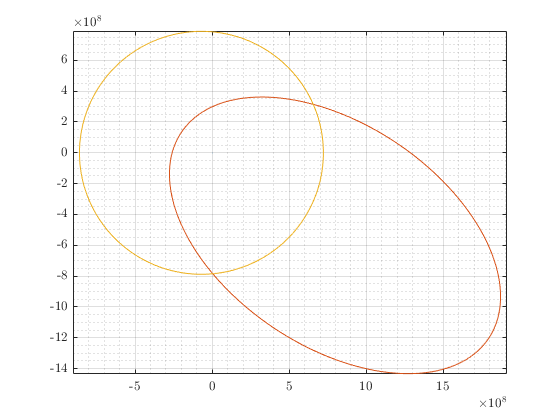

% Sketching
angles = 0:360;
% Sun
X_sun = sun.r * cosd(angles); Y_sun = sun.r * sind(angles);
% Comet 
R_comet = p_comet ./ (1 + e_comet * cosd(angles - Domega));
X_comet = R_comet .* cosd(angles); Y_comet = R_comet .* sind(angles);
% Jupiter 
R_jup = p_jup ./ (1 + e_jup * cosd(angles));
X_jup = R_jup .* cosd(angles); Y_jup = R_jup .* sind(angles);

plot(X_sun, Y_sun)
hold on; grid on; grid minor; box on; axis equal;
plot(X_comet, Y_comet)
plot(X_jup, Y_jup)
hold off

## Part (b)

% Find the flybly hyperbola characteristics 
v_inf_minus = sqrt(v_minus^2 + v_jup^2 - 2*v_minus*v_jup*cosd(abs(FPA_minus) + FPA_jup)) % Velocity of v-infinity 

v_inf_minus = 13.0864

E_fb = v_inf_minus^2 / 2  % specific energy of the flyby hyp

E_fb = 85.6269

a_fb = -jupiter.gp / 2 / E_fb  % SMA of the flyby hyp

a_fb = -7.5911e+05

rp_fb = 25 * jupiter.r  % periapsis of the fyby hyp

rp_fb = 1750000

e_fb = 1 - rp_fb / a_fb  % eccentricity of the flyby hyp

e_fb = 3.3053

delta = 2*asind(1 / e_fb)  % turning angle of the flyby hyp

delta = 35.2206

## Part (c)

% Find the conditions after flyby
eta = asind(v_minus / v_inf_minus * sind(abs(FPA_minus) + FPA_jup))  % angle we need 

eta = 70.2001

v_inf_plus = v_inf_minus;  % v-infinity plus
v_plus = sqrt(v_jup^2 + v_inf_plus^2 - 2*v_jup*v_inf_plus*cosd(delta + eta))  % velocity after flyby

v_plus = 20.7540

r_plus = r_minus;  % radial distance after flyby (does not change)
epsilon = asind(v_inf_plus / v_plus * sind(delta + eta))  % angle we need

epsilon = 37.4342

FPA_plus = epsilon - FPA_jup  % flight path angle after flyby

FPA_plus = 32.4342

## Part (d)

Dv_eq = sqrt(v_plus^2 + v_minus^2 -2*v_plus*v_minus*cosd(-FPA_minus - FPA_plus))  % delta-V 

Dv_eq = 7.9183

beta = asind(v_minus / Dv_eq * sind(-FPA_minus - FPA_plus))  % angle we need

beta = 35.2446

alpha = (-FPA_minus - FPA_plus) + beta

alpha = 52.9803